# 3-D  Trajectory planning with a straight-line path in the robot joint space and a trapezoidal velocity profile for time scaling T=0.9821s

## Construct The Robot

clc; clear;

robot = importrobot('Franka_Emika_Panda.urdf');

robot.DataFormat = 'column';

Show details of the robot to validate the input properties. The robot should have two non-fixed joints, where the link bodies are connected to their parent bodies via a revolute joint, and the end effector is connected to its parent body via a fixed joint.

showdetails(robot)

--------------------
Robot: (9 bodies)

 Idx      Body Name     Joint Name     Joint Type      Parent Name(Idx)   Children Name(s)
 ---      ---------     ----------     ----------      ----------------   ----------------
   1          link1         joint1       revolute              link0(0)   link2(2)  
   2          link2         joint2       revolute              link1(1)   link3(3)  
   3          link3         joint3       revolute              link2(2)   link4(4)  
   4          link4         joint4       revolute              link3(3)   link5(5)  
   5          link5         joint5       revolute              link4(4)   link6(6)  
   6          link6         joint6       revolute              link5(5)   link7(7)  
   7          link7         joint7       revolute              link6(6)   b_frame(8)  
   8        b_frame        b_frame          fixed              link7(7)   
   9        s_frame        s_frame          fixed              link0(0)   
--------------------


robot.homeConfiguration

ans =          0
         0
         0
   -1.5708
         0
         0
         0


panda_model()
M

M =     1.0000         0         0    0.0880
         0   -1.0000         0         0
         0         0   -1.0000    0.9260
         0         0         0    1.0000


B

B =          0         0         0         0         0         0         0
         0   -1.0000         0    1.0000         0    1.0000         0
   -1.0000         0   -1.0000         0   -1.0000         0    1.0000
         0    0.5930         0   -0.2770         0    0.1070         0
   -0.0880         0   -0.0880         0   -0.0880         0         0
         0    0.0880         0   -0.0055         0   -0.0880         0


S

S =          0         0         0         0         0         0         0
         0    1.0000         0   -1.0000         0   -1.0000         0
    1.0000         0    1.0000         0    1.0000         0   -1.0000
         0   -0.3330         0    0.6490         0    1.0330         0
         0         0         0         0         0         0    0.0880
         0         0         0   -0.0825         0         0         0


## Define The Trajectory

#### **Control random number generator**

rng default

### **Choose two arbitrary and feasible desired configurations**

**Start Configuration**

First, an arbitrary and feasible configuration has been chosen for start configuration. 

Tsd_start = [0 0 -1 0.36; 0 -1 0 0; -1 0 0 0.64; 0 0 0 1];
vpa(Tsd_start)

$$ans = \left(\begin{array}{cccc} 0 & 0 & -1.0 & 0.36\\ 0 & -1.0 & 0 & 0\\ -1.0 & 0 & 0 & 0.64\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

Now, using Inverse Kinematic, the corresponding joint angles can be obtained.

q_start = IK_SpaceForm(Tsd_start, [0; 0; 0; -pi/2; 0; 0; 0], [1e-3, 1e-3], S, M);
vpa(q_start', 4)

$$ans = \left(\begin{array}{ccccccc} 0 & 0 & 0 & -1.571 & 0 & 0 & 0 \end{array}\right)$$

To check the obtained joint angles, Forward Kinematc can be employed.

Tsd_start = round(FK_SpaceForm(S, M, q_start), 4);
vpa(Tsd_start)

$$ans = \left(\begin{array}{cccc} 0 & 0 & -1.0 & 0.3595\\ 0 & -1.0 & 0 & 0\\ -1.0 & 0 & 0 & 0.6435\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

**End Configuartion**

Now, an arbitrary configuration has been chosen for end configuration. For the sake of convenience we can choose an arbitrary joint angles to obtain T.


robot_finalconfig = [2.0457; 0.4303; -0.8637; -1.5310; -0.5690; 0.2689; -1.5071];
Tsd_end = FK_SpaceForm(S, M, robot_finalconfig);
vpa(Tsd_end, 4)

$$ans = \left(\begin{array}{cccc} -0.5932 & 0.7773 & -0.2097 & 0.1516\\ 0.07337 & -0.2072 & -0.9755 & 0.4353\\ -0.8017 & -0.5941 & 0.06592 & 0.5339\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

Using Inverse Kinematic, the corresponding joint angles can be obtained.

As the Inverse Kinematic is dependent on initial guess, it is better to obtain the end configuration using FK.

q_end = IK_SpaceForm(Tsd_end, [2.8; 0; -1.2; -1.5; -0.5; 0.3; -1.5], [1e-10, 1e-10], S, M);
vpa(q_end', 4)

$$ans = \left(\begin{array}{ccccccc} 2.403 & 1.002 & -1.562 & -1.655 & -0.6065 & 0.5917 & -2.212 \end{array}\right)$$

So, the end configuration can be obtained. It has the same position and slightly different orientation.

Tsd_end = FK_SpaceForm(S, M, q_end);
vpa(Tsd_end, 4)

$$ans = \left(\begin{array}{cccc} -0.5932 & 0.7773 & -0.2097 & 0.1516\\ 0.07337 & -0.2072 & -0.9755 & 0.4353\\ -0.8017 & -0.5941 & 0.06592 & 0.5339\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

**Start and End Configuration**

Now, start and end configuration cen be visualized.

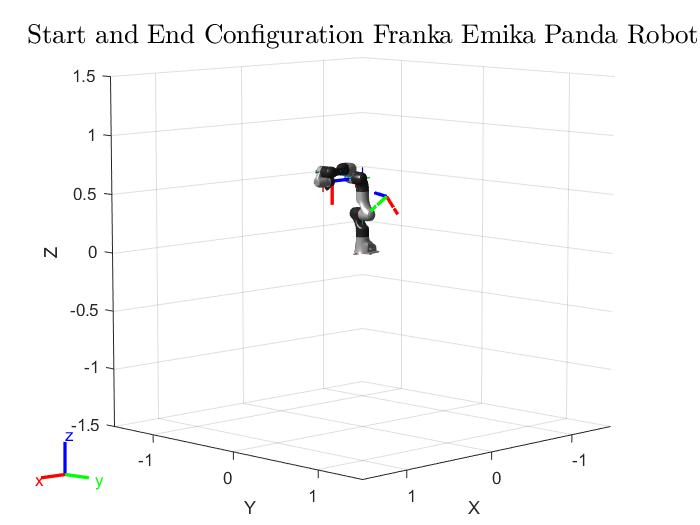

clf;
show(robot,q_start ,'Visuals','on');
hold on;
str = "Start and End Configuration Franka Emika Panda Robot";
title(str, FontSize=16, Interpreter="latex");
triad('Matrix',Tsd_start,'Scale',0.2,'LineWidth',2 ,'linestyle','-');
triad('Matrix',Tsd_end, 'Scale',0.2,'LineWidth',2 ,'linestyle','-.');

#### Define Trapezoidal Trajectory

Reference ([link](https://www.mathworks.com/help/robotics/ug/design-a-trajectory-with-velocity-limits-using-a-trapezoidal-velocity-profile.html))

First of all, we should define Way points, including start and end points.

frankaWaypoints = [q_start q_end];
vpa(frankaWaypoints', 5)

$$ans = \left(\begin{array}{ccccccc} 0 & 0 & 0 & -1.5708 & 0 & 0 & 0\\ 2.4033 & 1.0018 & -1.5619 & -1.655 & -0.60651 & 0.59173 & -2.212 \end{array}\right)$$

The velocity profile has four parameters:

- **End Time **— Duration of each segment between two waypoints

- **Peak Velocity **— Peak velocity for a each segment

- **Acceleration Time** — Time spent in the acceleration and deceleration phases of each segment

- **Peak Acceleration **— Magnitude of the acceleration applied during the acceleration and deceleration phases of each segment

peakVelocities = [150, 150, 150, 150, 180, 180, 180]'.*pi/180;
vpa(peakVelocities', 5)

$$ans = \left(\begin{array}{ccccccc} 2.618 & 2.618 & 2.618 & 2.618 & 3.1416 & 3.1416 & 3.1416 \end{array}\right)$$

peakAcceleration = [850, 425, 570, 700, 850, 1140, 1140]'.*pi/180;
vpa(peakAcceleration', 5)

$$ans = \left(\begin{array}{ccccccc} 14.835 & 7.4176 & 9.9484 & 12.217 & 14.835 & 19.897 & 19.897 \end{array}\right)$$

The `helperProfileForMaxVel` helper function  accepts a limiting segment velocity and outputs a set of end times and  velocities that ensure all dimensions have the same segment length, and  that the maximum velocity of any segment is less than or equal to the  specified velocity maximum.

**For a smooth path trajectory with minimum T, we can use **`helperProfileForMaxVel`** helper function to obtain endTimes for each join. It is obvious that minimum T is equal to the maximum time.**

q0 = q_start;
q1 = q_end;
for i = 1:size(q0)
    [endTimes(i, 1) ,peakVels(i, 1)] = helperProfileForMaxVel(frankaWaypoints (i, :), peakVelocities(i));
end

**Minimum T for each joint to perform the task.**

vpa(endTimes', 4)

$$ans = \left(\begin{array}{ccccccc} 1.01 & 0.4209 & 0.6562 & 0.03537 & 0.2124 & 0.2072 & 0.7745 \end{array}\right)$$

**Defining time vector **

t0 = 0; %Start Time
sampleRate = 50; % Sample Rate
tf = max(endTimes); %Final Time
t = (t0: 1/sampleRate : tf)'; % Time
numSamples = length(t);

## Constraints for Combining Parameter Specifications

The profile design results in two limiting constraints. The magnitude of the peak velocity must be:

- Peak velocity must be greater than the average speed: 

- Peak velocity must be less than or equal to twice the average speed:

These constraints are derived from the total segment length , which is fixed with any two waypoints and results from the integral of the velocity, i.e. the area of the trapezoid:

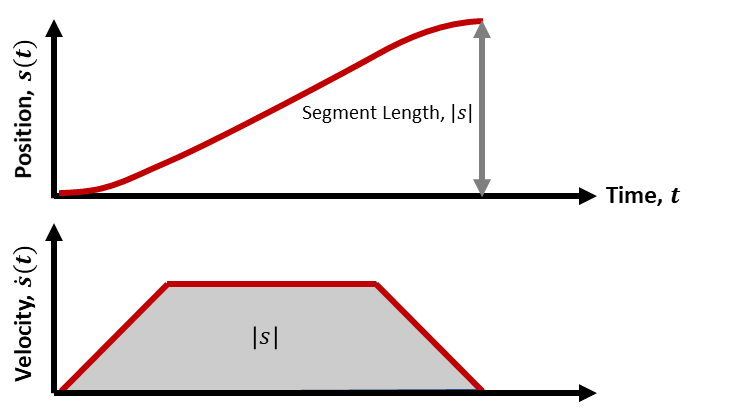

The first constraint sets the lowest allowable peak velocity magnitude. This occurs when the motion spends the most amount of time at constant speed: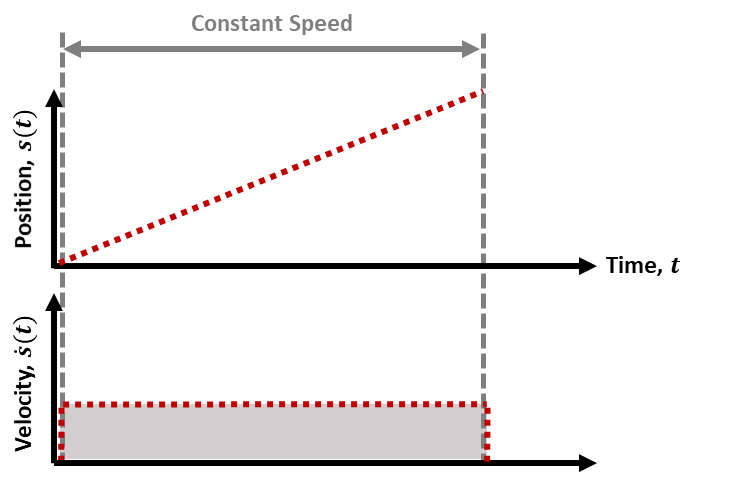

In the second case, the acceleration and deceleration phases are infinitesimal, resulting in a nearly rectangular velocity profile that has a total area , or . Hence for this case to succeed, the magnitude of the peak velocity must equal the average speed . In practice, the acceleration / deceleration phases can never be truly infinitesimal (Acceleration Time > 0), which instead makes this an inequality constraint: .

The second constraint defines the highest allowable peak velocity. This occurs when the motion spends as much time as possible accelerating to a peak velocity:

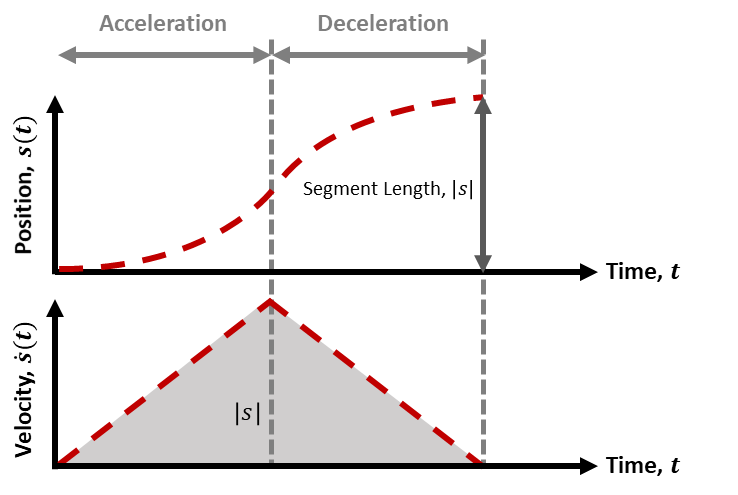

In this situation, there is no constant speed phase, resulting in a triangular velocity profile, which has a total area  or . Therefore, in this extreme, the magnitude of the peak velocity must equal twice the peak speed, resulting in the second constraint, .

These two constraints define the viable range of trapezoidal velocity profiles for a given segment. The following graphic compares three such trajectories, with the first constraint shown using dotted lines, the second shown with dashed lines, and an example of a trapezoidal profile within these constraints shown as a solid line. All plausible trapezoidal profile trajectories for this segment must fall between the dotted and dashed lines, as some variation of the solid line example. 

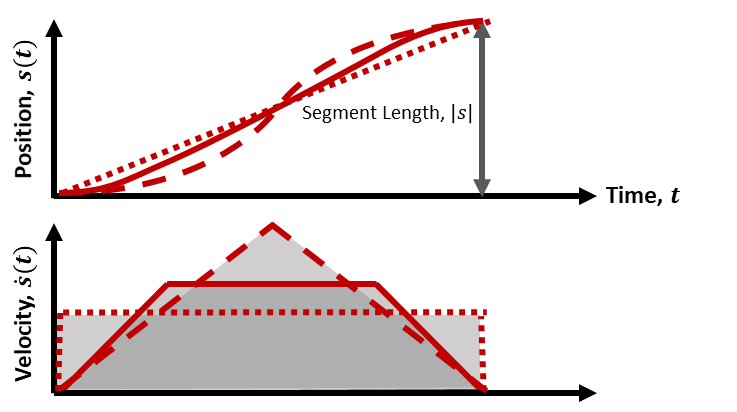

**Now, using the minimum T, peakVels for each joint can be obtained to satisfy above constraints.**

**Joint 1 has the maximum T to perform the task, so other joints peak velocities should be obtained based on the first joint.**

[endTimes ,peakVels] = helperProfileForMaxVel(frankaWaypoints, peakVelocities(1));
vpa(peakVels', 5)

$$ans = \left(\begin{array}{ccccccc} 2.618 & 1.9842 & 2.618 & 0.16673 & 1.2012 & 1.172 & 2.618 \end{array}\right)$$

**Now, a smooth trajectory can be computed such that satisfies all the velocity and acceleration constraints with T = 1.0098 s.**

[q,qd,qdd] = trapveltraj(frankaWaypoints,numSamples, PeakVelocity=peakVels, Acceleration=peakAcceleration);
q

q =          0    0.0036    0.0142    0.0320    0.0569    0.0889    0.1280    0.1742    0.2275    0.2848    0.3421    0.3994    0.4567    0.5140    0.5713    0.6286    0.6859    0.7432    0.8005    0.8578    0.9151    0.9724    1.0297    1.0871    1.1444    1.2017    1.2590    1.3163    1.3736    1.4309    1.4882    1.5455    1.6028    1.6601    1.7174    1.7747    1.8320    1.8893    1.9467    2.0040    2.0613    2.1186    2.1759    2.2292    2.2754    2.3145    2.3465    2.3713    2.3891    2.3998
         0    0.0018    0.0071    0.0160    0.0284    0.0444    0.0640    0.0871    0.1137    0.1439    0.1777    0.2150    0.2559    0.2992    0.3427    0.3861    0.4295    0.4730    0.5164    0.5598    0.6033    0.6467    0.6901    0.7336    0.7755    0.8138    0.8486    0.8798    0.9075    0.9316    0.9522    0.9692    0.9826    0.9925    0.9989    1.0017    1.0018    1.0018    1.0018    1.0018    1.0018    1.0018    1.0018    1.0018    1.0018    1.0018    1.0018    1.0018    1.0018    1

## Animate the Solution

Plot the robot for each frame of the solution using that specific robot configuration. Also, plot the desired trajectory.

Show the robot in the first configuration of the trajectory. Plot the desired trajectory.

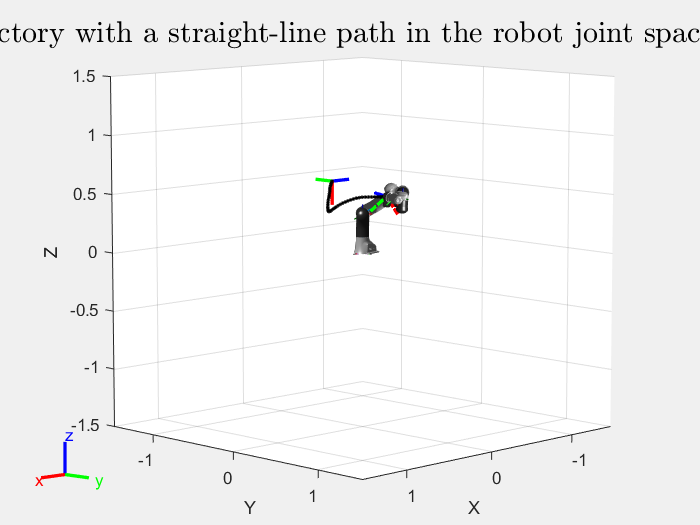

figure;
set(gcf,"Visible","on");
rc = rateControl(sampleRate);
show(robot,q_start ,'Visuals','on');
hold on;

str = "Smooth trajectory with a straight-line path in the robot joint space, T = " + num2str(tf) + " s";
title(str, FontSize=18, Interpreter="latex");

triad('Matrix',Tsd_start,'Scale',0.2,'LineWidth',2 ,'linestyle','-');
triad('Matrix',Tsd_end, 'Scale',0.2,'LineWidth',2 ,'linestyle','-.');
for i = 1:numSamples
    show(robot,q(:,i),FastUpdate=true, PreservePlot=false);
    drawnow;
    hold on
    T = FK_BodyForm(B, M, q(:,i));
    X = T(1, 4);
    Y = T(2, 4);
    Z = T(3, 4);
    scatter3(X, Y, Z, 'black.');
    waitfor(rc);
end

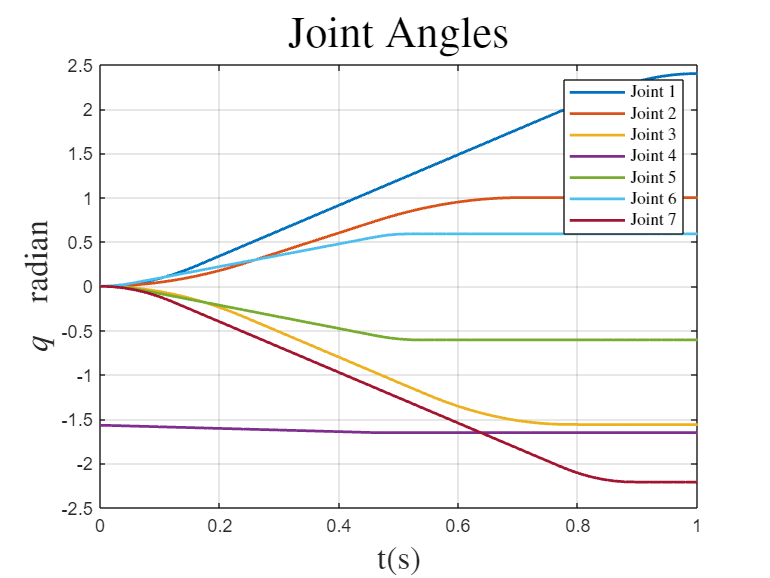

figure;

plot(t,q, LineWidth=1.5)
title('Joint Angles', Interpreter='latex', FontSize=24);
legend('Joint 1','Joint 2','Joint 3','Joint 4','Joint 5','Joint 6','Joint 7', 'Interpreter', 'latex');
ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

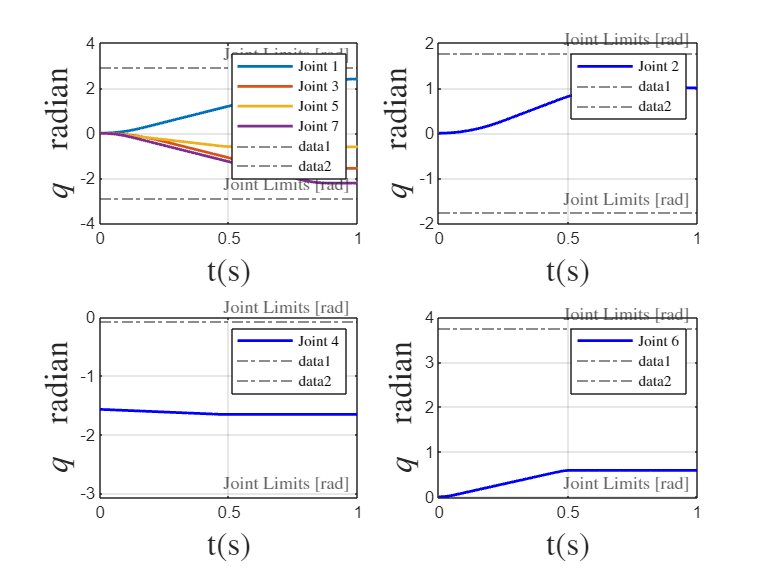

clf; figure;
title('Joint Angles', Interpreter='latex', FontSize=24);

subplot(2, 2, 1);
plot(t,q(1, :), LineWidth=1.5)
hold on;
plot(t,q(3, :), LineWidth=1.5)
hold on;
plot(t,q(5, :), LineWidth=1.5)
hold on;
plot(t,q(7, :), LineWidth=1.5)

legend('Joint 1','Joint 3','Joint 5','Joint 7', 'Interpreter', 'latex');
yline(panda.qlim(1, :),'-.','Joint Limits [rad]', Interpreter='latex');

ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;


subplot(2, 2, 2);
plot(t,q(2, :), LineWidth=1.5, Color='b')
legend('Joint 2', 'Interpreter', 'latex');
yline(panda.qlim(2, :),'-.','Joint Limits [rad]', Interpreter='latex');
ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

subplot(2, 2, 3);
plot(t,q(4, :), LineWidth=1.5, Color='b')
legend('Joint 4', 'Interpreter', 'latex');
yline(panda.qlim(4, :),'-.','Joint Limits [rad]', Interpreter='latex');
ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

subplot(2, 2, 4);
plot(t,q(6, :), LineWidth=1.5, Color='b')
legend('Joint 6', 'Interpreter', 'latex');
yline(panda.qlim(6, :),'-.','Joint Limits [rad]', Interpreter='latex');
ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

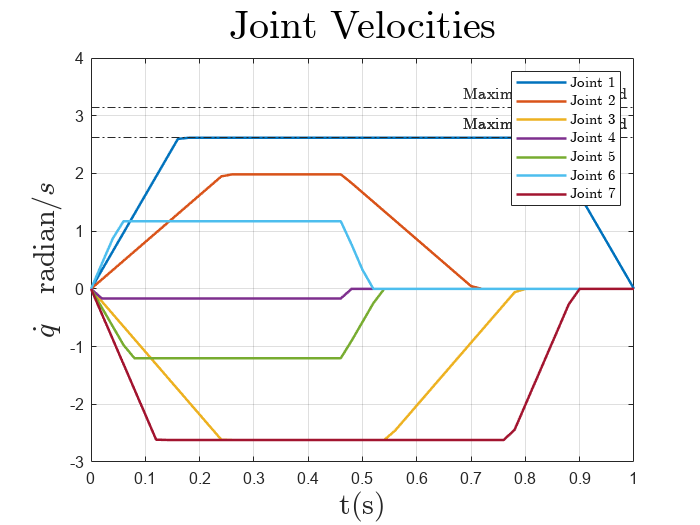


figure;
plot(t,qd, LineWidth=1.5)
yline(peakVelocities,'-.','Maximum Joint Speed', Interpreter='latex');
title('Joint Velocities', Interpreter='latex', FontSize=24);
legend('Joint 1','Joint 2','Joint 3','Joint 4','Joint 5','Joint 6','Joint 7', 'Interpreter', 'latex');
ylabel("$\dot{q} \quad {\textrm{radian}}/{s}$", Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

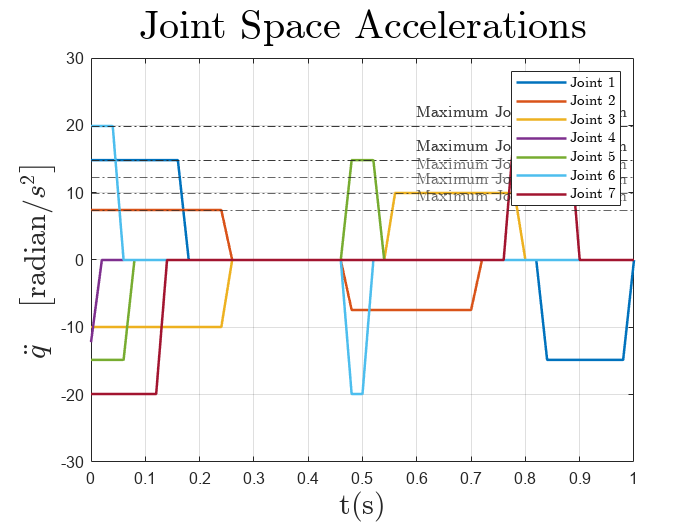


figure;
plot(t,qdd, LineWidth=1.5)

hold on;

yline(peakAcceleration,'-.','Maximum Joint Acceleration', Interpreter='latex');

title('Joint Space Accelerations', Interpreter='latex', FontSize=24);
legend('Joint 1','Joint 2','Joint 3','Joint 4','Joint 5','Joint 6','Joint 7', 'Interpreter', 'latex');
ylabel('$\ddot{q} \quad \left[ \textrm{radian}/ s^2 \right]$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
ylim([-30 30])
grid on;